We endeavor to develop a method to compute our resources at any arbitrary time $t$. 

The simple model provides a rates vector, which can be used to compute the future state. 

clear all
close all
clc
resources;
machines;
processes;

%t_step = 0.1;
%t = 0:t_step:10;
%net_resource_rates = A*x2*crafting_speed_factor;
%resources = net_resource_rates.*t;
%figure();
%plot(t,resources(21,:))

But it's not enough to have a static and unchanging factory. The factory must grow. A growing factory is represented by a change of the $\bf x$ matrix. 

%x2_0 = x2;
%x2_1 = x2_0;
%x2_1(9,12) = x2_0(9,12) - 2; % Remove two of the circuit producers
%net_resource_rates = A*x2_1*crafting_speed_factor;
%resources = net_resource_rates.*t;
%figure();
%plot(t,resources(21,:))

So we can change the matrix, but how do we represent the matrix changing at a particular time? If this were a continuous system we might need to just simulate every step of the process. But because it's linear, for now, we can probably just compute the slope between each time step. Let's say the update occurs at $t = 5$. 

Define an "action" to be an instantaneous change of the system state and control matrix. An action represents something the player can do, like placing down a machine. A complete description of the system would be a set of initial conditions and a list of actions taken at discrete times. Ideally the action of placing a machine should involve updating the machines matrix and also 

% Construct an initial action based on the solver's output
action_0 = new_action({ ...
    "iron_mining", "electric_mining_drill", 30;
    "copper_mining", "electric_mining_drill", 45;
    "iron_plate_smelting", "electric_furnace", 24;
    "copper_plate_smelting", "electric_furnace", 36;
    "copper_cable_crafting", "assembling_machine_3", 9;
    "circuit_crafting", "assembling_machine_3", 6;
});
process_matrix = action_0;
display_rates(A*process_matrix*crafting_speed_factor);

electronic_circuit: 15



% Remove an assembling machine to let copper cables back up
action_1 = new_action({"circuit_crafting", "assembling_machine_3", -2});
process_matrix = process_matrix + action_1;
display_rates(A*process_matrix*crafting_speed_factor);

iron_plate: 5
copper_cable: 15
electronic_circuit: 10



% Over-produce the circuits to consume the backlog of materials
action_2 = new_action({"circuit_crafting", "assembling_machine_3", 4});
process_matrix = process_matrix + action_2;
display_rates(A*process_matrix*crafting_speed_factor);

iron_plate: -5
copper_cable: -15
electronic_circuit: 20



% Remove them again to go back to equilibrium.
action_3 = new_action({"circuit_crafting", "assembling_machine_3", -2});
process_matrix = process_matrix + action_3;
display_rates(A*process_matrix*crafting_speed_factor);

electronic_circuit: 15



initial_resource_values = new_rate_vector({"iron_plate", 10; "copper_cable", 30});
display_rates(initial_resource_values);

iron_plate: 10
copper_cable: 30


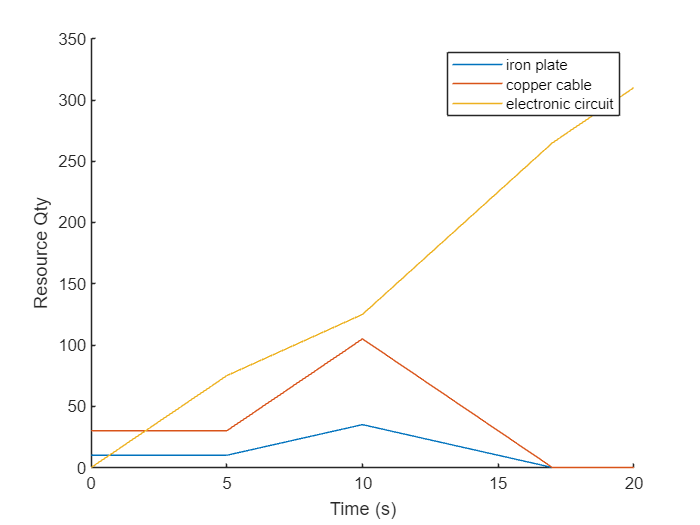


rate_matrix = action_0;
resource_result_samples = initial_resource_values;
gross_rates_samples = gross_rates(A,rate_matrix*crafting_speed_factor);
actions = {action_0, action_1, action_2, action_3};
times =   [0         5         10        17       20]; % One more time than action
for i=2:length(times)
    delta_t = times(i) - times(i-1);
    rate_vector = A*rate_matrix*crafting_speed_factor;
    resource_result_samples(:,i) = resource_result_samples(:,i-1) + rate_vector*delta_t;
    if(i <= length(actions))
        rate_matrix = rate_matrix  + actions{i};   
    end
    gross_rates_samples = [gross_rates_samples gross_rates(A,rate_matrix*crafting_speed_factor)];
end

%%
figure();
hold on;
% Find rows of the results that are non-zero
[rows,~]=find(resource_result_samples);
rows = sort(unique(rows));
legend_values = [];
for i=1:length(rows)
    plot(times,resource_result_samples(rows(i),:));
    legend_values = [legend_values item_names(rows(i))];
end
legend(strrep(legend_values,'_',' '));
xlabel("Time (s)");
ylabel("Resource Qty");

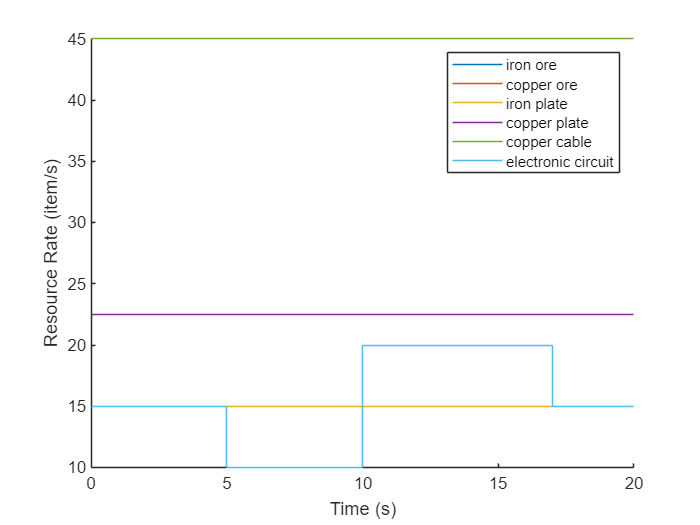


%%
figure();
hold on;
[rows,~]=find(gross_rates_samples);
rows = sort(unique(rows));
legend_values = [];
for i=1:length(rows)
    stairs(times,gross_rates_samples(rows(i),:));
    legend_values = [legend_values item_names(rows(i))];
end
legend(strrep(legend_values,'_',' '));
xlabel("Time (s)");
ylabel("Resource Rate (item/s)");